clc;clear;close all

T = 16; t = linspace(0,10*T,1000);
r1 = 1.5; r2 = 0.75; r3=0.5;
p1r = r1*sin(2*pi*t/T);
p2r = r2*sin(4*pi*t/T);
p3r = -0.5 + r3*sin(2*pi*t/T);

%translational 
p1_0 = 0;  p2_0 = 0; p3_0 = 0; 
v1_0 = 0;  v2_0 = 0; v3_0 = 0;
  
% Pendulum
alpha_0 = 0*pi/180; beta_0 = 0;
alpha_dt_0 = 0; beta_dt_0 = 0;

IC1= [p1_0;  p2_0;  p3_0;  alpha_0;    beta_0; v1_0;  v2_0;  v3_0;  alpha_dt_0; beta_dt_0];

M1 = [1.6, 0.16, 0.7];
A4 = [0 1 0 0 ; 0 0 1 0 ; 0 0 0 1  ;  0 0 0 0 ];
B4 = [0;0;0;1];

A2 = [0 1;0 0];
B2 = [0;1];

Q4 = 10*diag(ones(4,1));
% Q4(1,1) = 1;Q4(2,2)=1;Q4(3,3)=1;
R4 = diag(ones(1,1));

Q2 = 5*diag(ones(2,1));
R2 = diag(ones(1,1));
[Kv4,S,e] = lqr(A4,B4,Q4,R4);
[Kv2,S,e] = lqr(A2,B2,Q2,R2);

Kv = [flip(Kv2),0,0;
flip(Kv4);
flip(Kv4);];

% A = [0 1 0 0 0 0 0 0 0 0 0 0; 0 0 1 0 0 0 0 0 0 0 0 0; 0 0 0 1 0 0 0 0 0 0 0 0; 0 0 0 0 0 0 0 0 0 0 0 0; 0 0 0 0 0 1 0 0 0 0 0 0; 0 0 0 0 0 0 1 0 0 0 0 0; 0 0 0 0 0 0 0 1 0 0 0 0; 0 0 0 0 0 0 0 0 0 0 0 0; 0 0 0 0 0 0 0 0 0 1 0 0; 0 0 0 0 0 0 0 0 0 0 1 0; 0 0 0 0 0 0 0 0 0 0 0 1; 0 0 0 0 0 0 0 0 0 0 0 0;];
% 
% B = [0 0 0; 0 0 0; 0 0 0; 1 0 0; 0 0 0; 0 0 0; 0 0 0; 0 1 0; 0 0 0; 0 0 0; 0 0 0; 0 0 1;];
% 
% Q = diag(ones(12,1));
% Q(1,1) = 100;
% Q(5,5) = 100;
% Q(9,9) = 100;
% R = diag(0.1*ones(3,1));
% [Kv,S,e] = lqr(A,B,Q,R);

%Set 1
[t1,x1]=ode45(@(t,x)PTEdyn1(t,x,Kv,M1), [0,40],IC1);

%Calculate Load Position
h10 = [];
h20 = [];
h30 = [];
for i = 1:size(x1)
h10 = [h10;x1(i,1) + M1(3)*sin(x1(i,5))];
h20 = [h20;x1(i,2) - M1(3)*sin(x1(i,4))*cos(x1(i,5))];
h30 = [h30;x1(i,3) + M1(3)*cos(x1(i,5))*cos(x1(i,4))];
end
h1 = [h10,h20,h30];


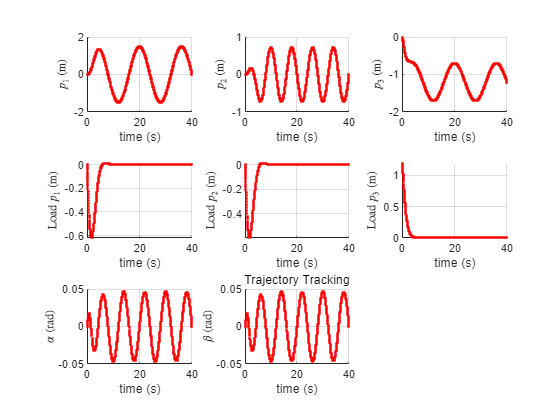

% Plotting
h(1) = figure; hold on; 

subplot(3,3,1); hold on;
plot(t1,x1(:,1),'.r'); grid on; 
xlim([0 40])
xlabel('time (s)')
ylabel('$p_1$ (m)','Interpreter',"latex")


subplot(3,3,2); hold on; 
plot(t1,x1(:,2),'.r'); grid on; 
xlim([0 40])
xlabel('time (s)')
ylabel('$p_2$ (m)','Interpreter',"latex")


subplot(3,3,3); hold on;
plot(t1,x1(:,3),'.r'); grid on;
xlim([0 40])
xlabel('time (s)')
ylabel('$p_3$ (m)','Interpreter',"latex")
% legend('True Param','1.5*Param','0.5*Param', 'Location','Best')

subplot(3,3,4); hold on;
plot(t1,h1(:,1)-(r1*sin(2*pi*t1/T)),'.r'); grid on; 
xlim([0 40])
% plot(t,p1r,'.m')
xlabel('time (s)')
ylabel('Load $p_1$ (m)','Interpreter',"latex")


subplot(3,3,5); hold on; 
plot(t1,h1(:,2)-r2*sin(4*pi*t1/T),'.r'); grid on; 
xlim([0 40])
% plot(t,p2r,'.m')
xlabel('time (s)')
ylabel('Load $p_2$ (m)','Interpreter',"latex")


subplot(3,3,6); hold on;
plot(t1,h1(:,3)-(-0.5 + r3*sin(2*pi*t1/T)),'.r'); grid on; 
xlim([0 40])
% plot(t,p3r,'.m')
xlabel('time (s)')
ylabel('Load $p_3$ (m)','Interpreter',"latex")


subplot(3,3,7); hold on;
plot(t1,x1(:,4),'.r'); grid on; 
xlim([0 40])
xlabel('time (s)')
ylabel('$\alpha$ (rad)','Interpreter',"latex")


subplot(3,3,8); hold on;
plot(t1,x1(:,4),'.r'); grid on;
xlim([0 40])
xlabel('time (s)')
ylabel('$\beta$ (rad)','Interpreter',"latex")

% subplot(3,3,9); hold on;
% plot(t1,h1(:,2)-r2*sin(4*pi*t1/T),'.r'); grid on;
% xlim([0 40])
% xlabel('time (s)')
% ylabel('$\beta$ (rad)','Interpreter',"latex")

subtitle('Trajectory Tracking')

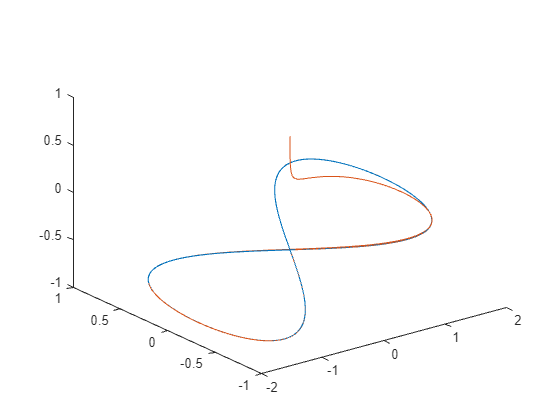

a = figure();
plot3(p1r,p2r,p3r);
hold on
plot3(h1(:,1),h1(:,2),h1(:,3));

% filename = sprintf("TrajectoryTrack.pdf");
% exportgraphics(h(1),filename);